# Operaciones matriciales

Las operaciones matriciales dentro de MATLAB siguen las **reglas del álgebra lineal** que se estudian en el instituto o en la universidad.

Para obtener más información, o un breve repaso, puede consultar el material adjunto el material adicional.

## Operaciones matriciales

En la siguiente tabla se muestran las operaciones matriciales de las que se dispone dentro de MATLAB.

**Figura 1.** Todas las operaciones matriciales dentro de MATLAB.

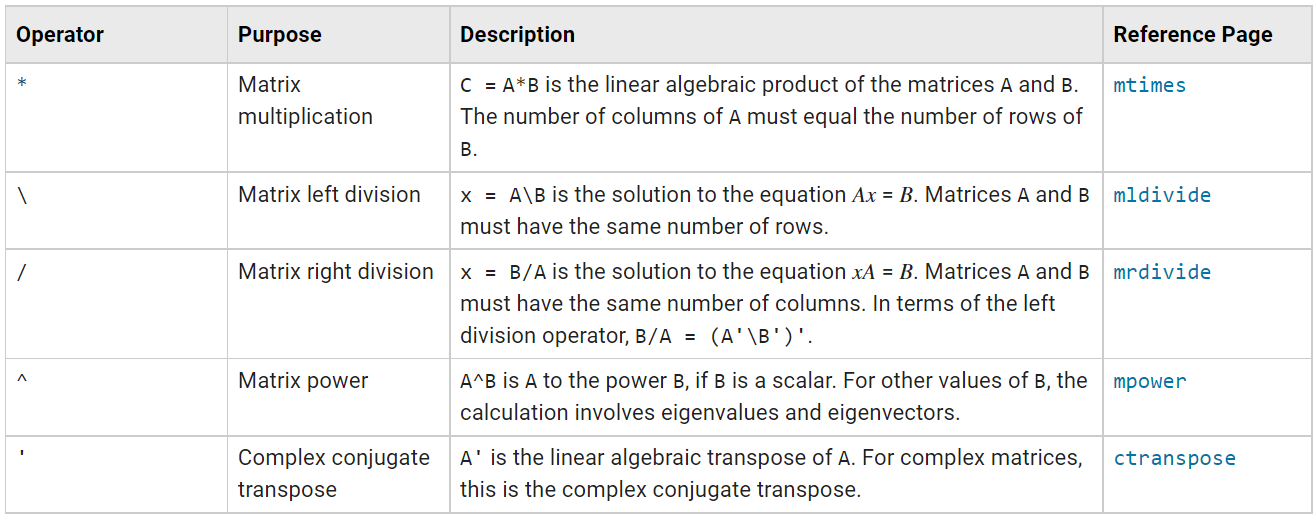

*Tomado de la documentación oficial de MATLAB.*

La suma y resta matricial son similares a la suma y resta tradicional (*operación elemento a elemento*). El resto de operaciones sí cambian significativamente.

## Multiplicación y potencia

El producto o multiplicación matricial se define como:


$$\textrm{AB}={\left(a_{\textrm{ij}} \right)}_{m\times n} {\left(b_{\textrm{ij}} \right)}_{n\times p} ={\left(\sum_{k=1}^n a_{\textrm{ik}} b_{\textrm{kj}} \right)}_{m\times p}$$


O escrito de otra forma:


$$\begin{array}{l}
\textrm{AB}=\left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & \ldotp \ldotp \ldotp  & a_{1n} \\
a_{21}  & a_{22}  & \ldotp \ldotp \ldotp  & a_{2n} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{m1}  & a_{m2}  & \ldotp \ldotp \ldotp  & a_{\textrm{mn}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
b_{11}  & b_{12}  & \ldotp \ldotp \ldotp  & b_{1p} \\
b_{21}  & b_{22}  & \ldotp \ldotp \ldotp  & b_{2p} \\
\vdots  & \vdots  & \ddots  & \vdots \\
b_{n1}  & b_{n2}  & \ldotp \ldotp \ldotp  & b_{\textrm{np}} 
\end{array}\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;=\left\lbrack \begin{array}{cccc}
a_{11} b_{11} +a_{12} b_{21} +\cdots +a_{1n} b_{n1}  & \sum_{k=1}^n a_{1k} b_{k2}  & \ldotp \ldotp \ldotp  & \sum_{k=1}^n a_{1k} b_{\textrm{kp}} \\
a_{21} b_{11} +a_{22} b_{21} +\cdots +a_{2n} b_{n1}  & \sum_{k=1}^n a_{2k} b_{k2}  & \ldotp \ldotp \ldotp  & \sum_{k=1}^n a_{2k} b_{\textrm{kp}} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{m1} b_{11} +a_{m2} b_{21} +\cdots +a_{\textrm{mn}} b_{n1}  & \sum_{k=1}^n a_{\textrm{mk}} b_{k2}  & \ldotp \ldotp \ldotp  & \sum_{k=1}^n a_{\textrm{mk}} b_{\textrm{kp}} 
\end{array}\right\rbrack 
\end{array}$$


**Figura 2.** Ejemplo de multiplicación matricial con calificaciones y ponderaciones.

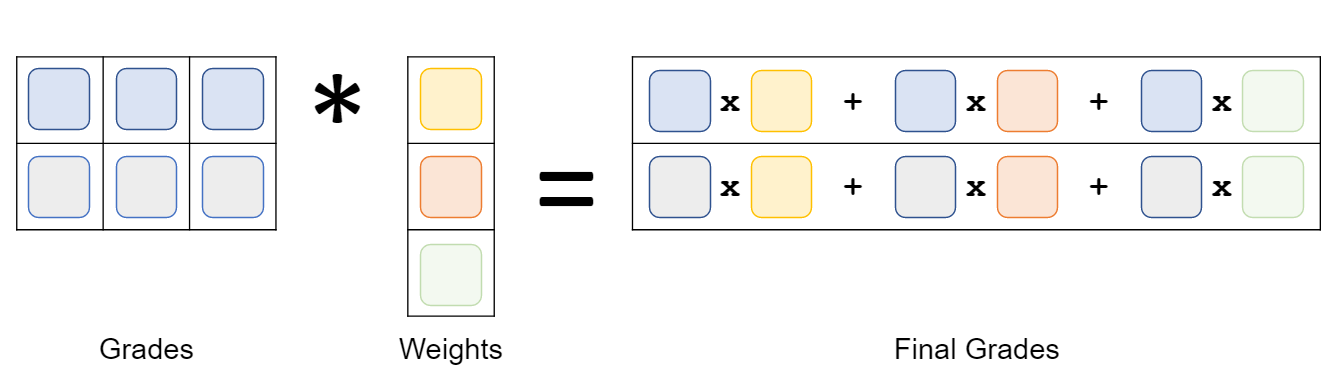

*Tomado de la documentación oficial de MATLAB.*

Un pequeño tip para verificar si una matriz se puede multiplicar con otra es observar el número de columnas de la matriz de la derecha y el número de filas de la matriz de la izquierda. Si estos números son iguales, entonces la multiplicación entre estas matrices es posible. Recordar que el producto matricial no es conmutativo, por ende, $\textrm{AB}\not= \textrm{BA}$.

**Figura 3.** Verificación de dimensiones para realizar la multiplicación matricial.

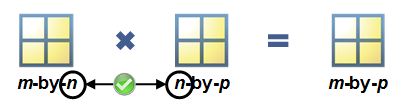

*Tomado de la documentación oficial de MATLAB.*

**Figura 4.** Matriz resultante de la multiplicación matricial.

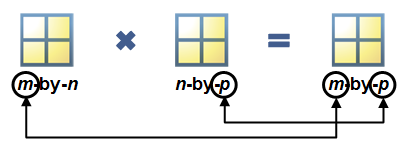

*Tomado de la documentación oficial de MATLAB.*

grades = randi(10,2,3)

grades =      1     5     2
     4     3     9


weight=[.5 .25 .25]'

weight =     0.5000
    0.2500
    0.2500


finalGrades=grades * weight

finalGrades =     2.2500
    5.0000


Por otra parte, la potencia de una matriz es posible únicamente para matrices cuadradas.

A=randi(3,5,5)

A =      2     3     3     3     3
     3     3     1     1     2
     2     2     3     3     1
     3     1     2     3     1
     2     3     3     2     2


A^2

ans =     34    33    33    33    24
    24    27    23    22    21
    27    24    26    28    18
    24    22    25    27    18
    29    29    28    28    21


### Ejercicio

Usted y un amigo van a una tienda. Sus listas son las que se muestran en la tabla.

**Figura 5.** Cantidad de artículos comprados por cada persona.

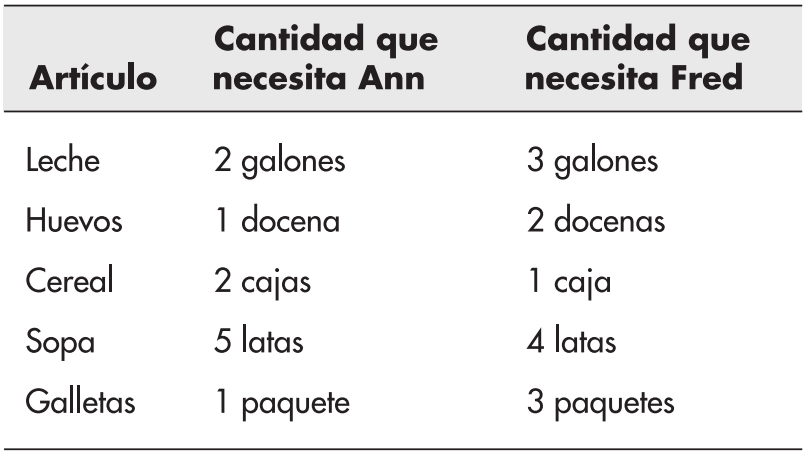

*Tomado de MATLAB para ingenieros de Holly Moore.*

Los artículos tienen los siguientes costos:

**Figura 6.** Precio unitario de cada artículo.

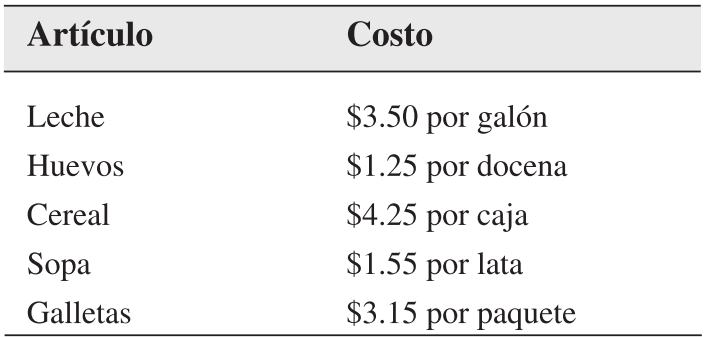

*Tomado de MATLAB para ingenieros de Holly Moore.*

Encuentre la factura total para cada comprador.

*Ejercicio tomado de Moore, 2007.*

### Solución

articulos=[2 3 ; 1 2; 2 1;5 4;1 3]'

articulos =      2     1     2     5     1
     3     2     1     4     3


disp(articulos)

     2     1     2     5     1
     3     2     1     4     3



costounitario=[3.5 1.5 4.24 1.55 3.15]'

costounitario =     3.5000
    1.5000
    4.2400
    1.5500
    3.1500


total=articulos*costounitario

total =    27.8800
   33.3900


sum(total)

ans = 61.2700

## División izquierda, división derecha y transposición

Las divisiones tanto izquierda como derecha dentro de MATLAB permiten resolver un sistema de ecuaciones lineales.

- La división izquierda (`\`) permite resolver el sistema $Ax = b$, donde $x=A\backslash b$. La matriz $A$ y el vector $b$ deben tener el mismo número de filas. El sistema ingresado debe ser similar al mostrado a continuación:


$$\begin{array}{l}
a_1 x_1 +a_2 x_2 +a_3 x_3 =b_1 \\
a_4 x_1 +a_5 x_2 +a_6 x_3 =b_2 \\
a_7 x_1 +a_8 x_2 +a_9 x_3 =b_3 
\end{array}$$



$$A=\left\lbrack \begin{array}{ccc}
a_1  & a_2  & a_3 \\
a_4  & a_5  & a_6 \\
a_7  & a_8  & a_9 
\end{array}\right\rbrack ,\;x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack ,\;b=\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 
\end{array}\right\rbrack$$


- La división derecha (`/`) permite resolver el sistema $xA = b$, donde $x = b/A$. La matriz $A$ y el vector $b$ deben tener el mismo número de columnas. El sistema ingresado debe ser similar al mostrado a continuación:


$$\begin{array}{l}
a_1 x_1 +a_2 x_2 +a_3 x_3 =b_1 \\
a_4 x_1 +a_5 x_2 +a_6 x_3 =b_2 \\
a_7 x_1 +a_8 x_2 +a_9 x_3 =b_3 
\end{array}$$



$$A=\left\lbrack \begin{array}{ccc}
a_1  & a_4  & a_7 \\
a_2  & a_5  & a_8 \\
a_3  & a_6  & a_9 
\end{array}\right\rbrack ,\;x=\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack ,\;b=\left\lbrack \begin{array}{ccc}
b_1  & b_2  & b_3 
\end{array}\right\rbrack$$


Donde $A$ es la matriz de coeficientes, $b$ es el vector columna de términos independientes y $x$ es el vector columna solución.

n=5;
a=randi([-10 10],n)

a =      1    -1    -3    -6    -8
     4     6    -9     9     5
    10     7     0     4     5
    -4    -8    -3    -1     1
    -2    -7    -7     9    -7


b=randi([-10 10],n,1)

b =      2
    -4
    -8
    -6
     8


x=a\b

x =    -1.0327
    0.8012
    0.5718
    0.7501
   -1.2563


Finalmente, la transposición matricial devuelve la conjugada de los elementos de la matriz. Esto es relevante cuando la matriz es compleja, es decir, sus elementos son números complejos.

c=[1-1i 2+6i; 1 1 ]

c =    1.0000 - 1.0000i   2.0000 + 6.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i


c.'

ans =    1.0000 - 1.0000i   1.0000 + 0.0000i
   2.0000 + 6.0000i   1.0000 + 0.0000i


### Ejercicio

Determinar las acciones internas, o fuerzas internas, y las reacciones de la siguiente armadura a través del método de los nodos generando el sistema de ecuaciones de la armadura.

**Figura 7.** Armadura.

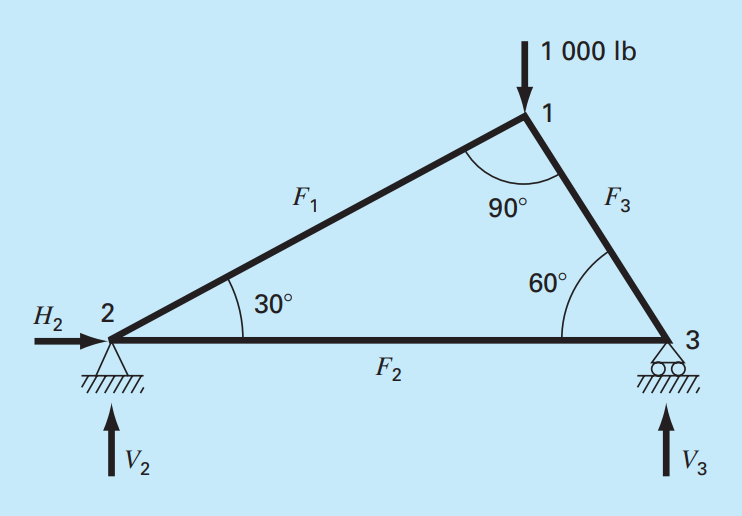

*Tomado de Métodos numéricos para ingenieros de Steven C. Chapra & Raymond P. Canale.*

*Ejercicio modificado de Chapra & Canale, 2007.*

### Solución

A=[cosd(30) 1 0 1 0 0;sind(30) 0 0 0 1 0; -cosd(30) 0 cosd(60) 0 0 0;sind(30) 0 sind(60) 0 0 0;0 -1 -cosd(60) 0 0 0; 0 0 sind(60) 0 0 1]

A =     0.8660    1.0000         0    1.0000         0         0
    0.5000         0         0         0    1.0000         0
   -0.8660         0    0.5000         0         0         0
    0.5000         0    0.8660         0         0         0
         0   -1.0000   -0.5000         0         0         0
         0         0    0.8660         0         0    1.0000


b=[0 0 0 -1e3 0 0]'

b =            0
           0
           0
       -1000
           0
           0


x=A\b

x =  -500.0000
  433.0127
 -866.0254
         0
  250.0000
  750.0000


## Material adicional

- [Matrices en el entorno de MATLAB](https://www.mathworks.com/help/matlab/math/matrices-in-the-matlab-environment.html)

- [Operaciones matriciales](https://www.mathworks.com/help/matlabmobile/ug/matrix-operations.html)

- [Operaciones arreglo vs. Operaciones matriciales](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html)